# Bayesian Learning

We are going to obtain data from a distribution $\mathcal{N}(5,2)$.

mu_true = 5;
sigma = 2;

num_samples = 10;

rng('default') % For reproducibility
data = mu_true + sigma_true * randn(num_samples, 1);

% Set up the x-axis for plotting
x = linspace(-5, 10, 1000);

% Plot the true distribution
figure;
hold on;
plot(x, normpdf(x, mu_true, sigma_true), 'LineWidth', 2);
title('Bayesian Learning');
xlabel('x');
ylabel('Probability Density');
xlim([-5, 10]);
legend('N(5, 2)');

Our prior is going to be a standard normal $\mu\sim\mathcal{N}(0,1)$ and we are going to assume that $\sigma$ is well approximated by the sample variance.

mu_prior = 0;
sigma_prior = 1;

Now, we are going to update our beliefs with the obtained datapoints, and the formulas for updating are:


$$\mu_{n}=\frac{\sigma_{0}^{2}\sum x_{i}+\sigma^{2}\mu_{0}}{\sigma^{2}+n\sigma_{0}^{2}}$$
 

and

$\sigma_{n}=\frac{\sigma^{2}\sigma_{0}^{2}}{\sigma^{2}+n\sigma_{0}^{2}}$.

mu_posterior = (sigma_prior^2*(sum(data))+var(data)*mu_prior)/(var(data)+num_samples*sigma_prior^2)

mu_posterior = 2.7734

sigma_posterior = (var(data)*sigma_prior^2)/(var(data)+num_samples*sigma_prior^2)

sigma_posterior = 0.5561


plot(x, normpdf(x, mu_posterior, sqrt(var(data))), 'LineWidth', 2);
xlabel('x');
ylabel('Probability Density');

sigma_prior = sigma_posterior;
mu_prior = mu_posterior;

data = mu_true + sigma_true * randn(num_samples, 1);

mu_posterior = (sigma_prior^2*(sum(data))+var(data)*mu_prior)/(var(data)+num_samples*sigma_prior^2)

mu_posterior = 4.0179

sigma_posterior = (var(data)*sigma_prior^2)/(var(data)+num_samples*sigma_prior^2)

sigma_posterior = 0.2034


plot(x, normpdf(x, mu_posterior, sqrt(var(data))), 'LineWidth', 2);
xlabel('x');
ylabel('Probability Density');

sigma_prior = sigma_posterior;
mu_prior = mu_posterior;

num_samples = 500;

data = mu_true + sigma_true * randn(num_samples, 1);

mu_posterior = (sigma_prior^2*(sum(data))+var(data)*mu_prior)/(var(data)+num_samples*sigma_prior^2)

mu_posterior = 4.7770

sigma_posterior = (var(data)*sigma_prior^2)/(var(data)+num_samples*sigma_prior^2)

sigma_posterior = 0.0064

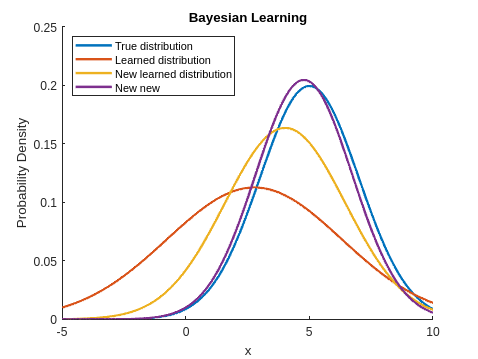

leg =   Legend (True distribution, Learned distribution, New learned distribution, New new) with properties:

         String: {'True distribution'  'Learned distribution'  'New learned distribution'  'New new'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1483 0.7446 0.3565 0.1545]
          Units: 'normalized'

  Show all properties



plot(x, normpdf(x, mu_posterior, sqrt(var(data))), 'LineWidth', 2);
xlabel('x');
ylabel('Probability Density');
leg = legend('True distribution', 'Learned distribution', 'New learned distribution', 'New new');
leg.Location = "northwest"